# Project #1 MATLAB Simulator

Dhruvit Manojkumar Mavani | M70570748

### ***Introduction***

The objective of the project 1 is to simulate three Dynamic systems namely **DS1**, **DS2** and **DS3** using disparate numerical integration method such as Forward Euler Integration, Adams-Basworth 2 integration, and Range-Kutta 4; and explore the different aspects of numerical integration method such as effect of reducing time step on the characteristic root error and, accuracy of the dynamic system simulation. Furthermore, how to identify or decide which integration method and time step is optimum for any particular simulation is also one of the objective of this project.

### *Forward Euler Integration*

Initially, we will discuss the three different numerical integration method used here, out of which first is; Forward euler integration, which is a first-order numerical integration method, and is used to solve the differential equation of any dynamic system. The difference equation of Euler integration method is

$x_{n+1} =x_n +\textrm{hf}\left(n\right)$                     .... (4)

The approximate characteristic root error formula for euler integration is

$e_{\lambda } \approx -\frac{1}{2}\left(\lambda h\right)$,     $|\lambda h|\ll 1$       .... (5)

### *Adams Basforth (AB-2) Integration method*

Adams Basforth (AB-2) is a second-order numerical integration method used to solve the differential equation of any dynamic system by evaluating two functions, $f_{n-1}$ and $f_n$. The difference equation of AB-2 integration method is

$x_{n+1} =x_n +\frac{1}{2}h\left(3f_n -f_{n-1} \right)$       .... (6)

The approximate characteristic root error formula for AB-2 integration method is

$e_{\lambda } \approx -\frac{5}{12}{\left(\lambda h\right)}^2$,     $|\lambda h|\ll 1$    .... (7) 

However, the probelm with AB-2 is that its difference equation includes the term $f_{n-1}$ which is undetermined at time $t=0$ and $t=h$. so , in this case euler is generally used for the initial time until $t=2h$.

### *RK-4 Integration method*

RK-4 integration method is also known as Range-Kutta fourth order integration method and it evaluates the four functions $f_{n\;} ,\;{\overset{}{\overset{\wedge }{f} } }_{n+\frac{1}{2}}$, ${\overset{\wedge }{\overset{\wedge }{f} } }_{n+\frac{1}{2}}$, and ${\overset{\wedge }{f} }_{n+1}$. The differece equation of AB-2 integration method is

$x_{n+1} =x_n +\frac{h}{6}\left(f_n +2{\overset{}{\overset{\wedge }{f} } }_{n+\frac{1}{2}} +2{\overset{\wedge }{\overset{\wedge }{f} } }_{n+\frac{1}{2}} +{\overset{\wedge }{f} }_{n+1} \right)$      .... (8)

The approximate characteristic root error formula for RK-4 integration method is

$e_{\lambda } \approx -\frac{6}{720}{\left(\lambda h\right)}^4$,     $|\lambda h|\ll 1$                       .... (9)

As we had discussed different numerical integration method, now its time to describe our three dynamic systems DS1, DS2, and DS3 and simulate it.

### *Dynamic system 1*

Dynamic system 1 is a linear time-invariant system having differential equation

$\overset{\ldotp }{\mathit{\mathbf{x}}} +4\mathit{\mathbf{x}}=\mathit{\mathbf{u}}$,    $x\left(0\right)=2$                            .... (10)

$\overset{\ldotp }{\underset{-}{x}} =\underset{-}{f} \;\left\lbrack -4x+u\right\rbrack$    State Equation

$\underset{-}{y} =\underset{-}{g} \;\left\lbrack x\right\rbrack$               Output Equation

The DS-1 is simulated using **Forward Euler Integration** method at time step, $h=0\ldotp 01\;s$.

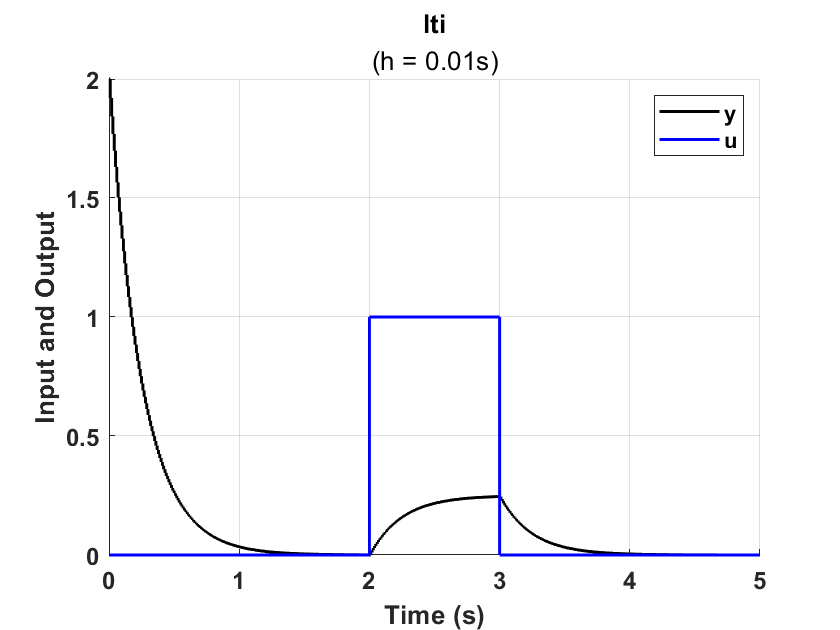

%% Run and Analyze Simulation Results
% After cleaning up the workspace, the simulator just needs a few lines of
% code: define the dynamic system using a cell array, call the
% simulator and finally plot the results.

%% Cleanup
clearvars;
close('all');
 
%% LTI Analysis
dsName = 'lti';
mySS = pickDynamicSystem(dsName);

% Euler Analysis
[eu.t, eu.y, eu.u] = mySim(mySS,5.0,0.01,'euler');
ltiEU = plotData(eu,dsName);

   Fig.1 LTI system simulation result (Euler)

% AB-2 Analysis
%[ab.t, ab.y, ab.u] = mySim(mySS,5.0,0.01,'ab2'  );
%ltiAB = plotData(ab,dsName);

% RK-4 Analysis
%[rk.t, rk.y, rk.u] = mySim(mySS,5.0,0.01,'rk4'  );
%ltiRK = plotData(rk,dsName);

### *Dynamic system 2*

Dynamic system 2 is a linear time-varying system with differential equation

$\mathit{\mathbf{m}}\overset{\ldotp \ldotp }{\mathit{\mathbf{w}}} +\mathit{\mathbf{c}}\overset{\ldotp }{\mathit{\mathbf{w}}} +\mathit{\mathbf{k}}\left(\mathit{\mathbf{t}}\right)\mathit{\mathbf{w}}=\mathit{\mathbf{u}},\;\;\;w\left(0\right)=\overset{\ldotp }{w} \left(0\right)=0$        .... (11)

where,  $m=1\;\textrm{kg}$, $c=0\ldotp 5\;$N/(m/s), and $k\left(t\right)=30+3\sin \left(2\pi t\right)$ N/m,  $u\left(t\right)=100\sin \left(8\pi t\right)$

$\overset{\ldotp }{\underset{-}{x}} =\underset{-}{f} \;\;\left\lbrack \begin{array}{c}
x_2 \\
-\frac{k\left(t\right)}{m}x_1 -\frac{c}{m}x_2 +\frac{1}{m}u
\end{array}\right\rbrack$    State equation

$\underset{-}{y} =\underset{-}{g} \;\left\lbrack x_1 \right\rbrack$                                    Output equation

Linear time-varying system is simulated using **AB-2 Integration** method at time step, $h=0\ldotp 01\;s$

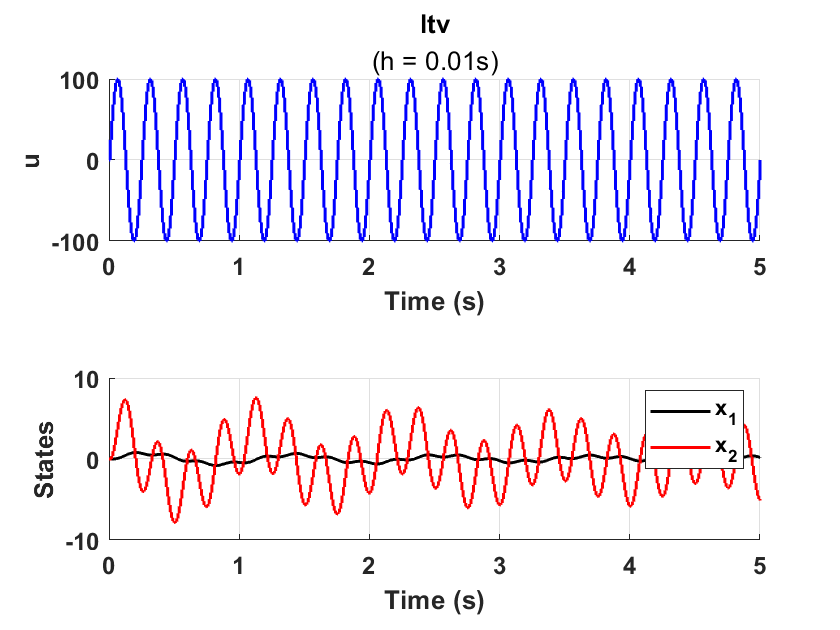

%% LTV Analysis
dsName = 'ltv';
mySS = pickDynamicSystem(dsName);

% Euler Analysis
[eu.t, eu.y, eu.u] = mySim(mySS,5.0,0.01,'ab2');
ltvEU = plotData(eu,dsName);

Fig.2 LTV system simulation result (AB-2)

% AB-2 Analysis
%[ab.t, ab.y, ab.u] = mySim(mySS,5.0,0.01,'ab2'  );
%ltvAB = plotData(ab,dsName);
% RK-4 Analysis
%[rk.t, rk.y, rk.u] = mySim(mySS,5.0,0.01,'rk4'  );
%ltvRK = plotData(rk,dsName);

### *Dynamic system 3*

Dynamic system 3 is a nonlinear time-invariant Vanderpol differential equation

$\overset{\ldotp \ldotp }{\mathit{\mathbf{w}}} -\mu \left(1-{\mathit{\mathbf{w}}}^2 \right)\overset{\ldotp }{\mathit{\mathbf{w}}} +\mathit{\mathbf{w}}=\mathit{\mathbf{u}},$    $w\left(0\right)=\overset{\ldotp }{w} \left(0\right)=0$       .... (12)

where, $\mu =8\ldotp 53$ and $u\left(t\right)=1\ldotp 2\sin \left(0\ldotp 2\pi t\right)$

$\overset{\ldotp }{\underset{-}{x}} =\underset{-}{f} \;\;\left\lbrack \begin{array}{c}
x_2 \\
-x_1 +\mu \left(1-x_1^2 \right)x_2 +u
\end{array}\right\rbrack$  State Equation

$\underset{-}{y} =\underset{-}{g} \;\left\lbrack x_1 \right\rbrack$                                     Output Equation

The dynamic system 3 (VDP) is simulated using **RK-4 (Range-kutta) Integration** method at time step, $h=0\ldotp 01s\ldotp$

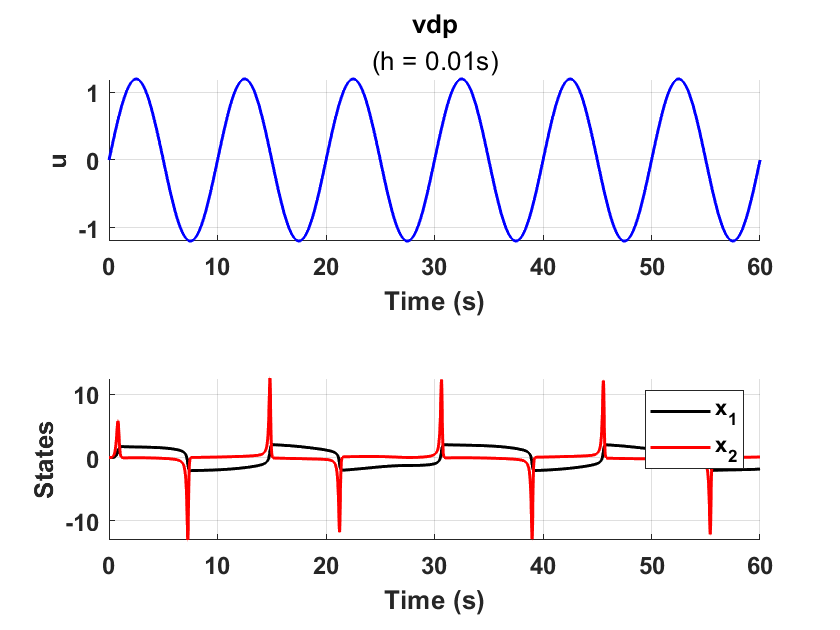

%% VDP Analysis
dsName = 'vdp';
mySS = pickDynamicSystem(dsName);

% Euler Analysis
%[eu.t, eu.y, eu.u] = mySim(mySS,60,0.001,'euler');
%vdpEU = plotData(eu,dsName);
% AB-2 Analysis
%[ab.t, ab.y, ab.u] = mySim(mySS,5.0,0.01,'ab2'  );
%ltvAB = plotData(ab,dsName);
% RK-4 Analysis
[rk.t, rk.y, rk.u] = mySim(mySS,60,0.01,'rk4');
vdpRK = plotData(rk,dsName);

Fig.3 VDP simulation results (RK-4)

### *Simulation Verification*

As we have simulated our systems DS-1, DS-2 & DS-3 using different integration methods, we still don't know if our simulation is wrong or right. So,now we will verify our simulation by looking at the errors associated with Euler,AB-2 and RK-4 and see how skewed our simulation is to the exact solution. Here, for Simulation verification the time step is set to $h=0\ldotp 01s$. Now, we know that for $|\lambda h|\ll 1$, **euler error **$e_{\lambda } =-\frac{1}{2}\lambda h$; error for **AB-2 integration **$e_{\lambda } =-\frac{5}{12}{\lambda h}^2$; and error induced due to **RK-4 integration **method $e_{\lambda } =-\;{\frac{6}{720}\lambda h}^4$. From Fig.4 we can see that between $t=0\ldotp 02\;\&\;t=0\ldotp 03$ the magnitude of Euler error is $0\ldotp 00303$, magnitude of AB-2 error is $0\ldotp 00143$ and magnitude of RK-4 error is$\;3\ldotp 25776e^{-9}$.

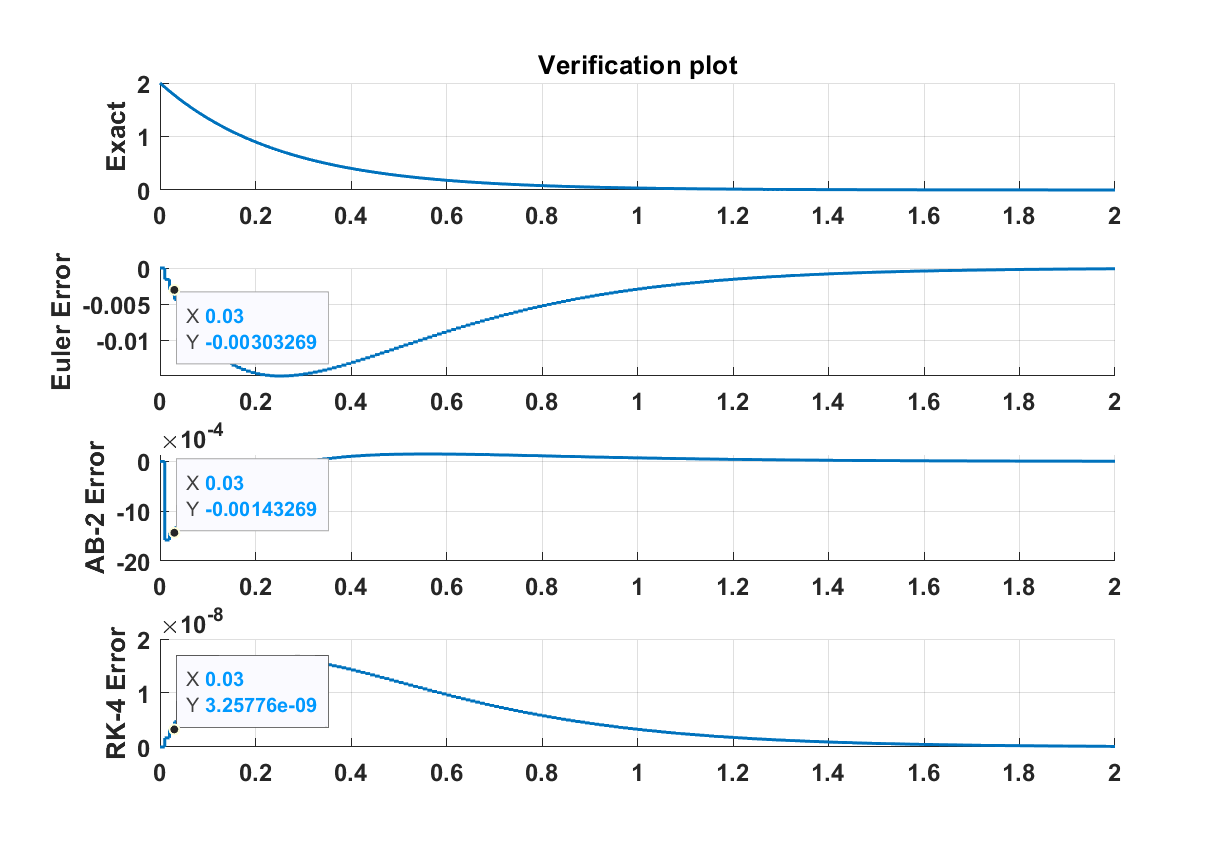

%% Verification
verificationPlot = verifyLTI;  %% Comparisons

Fig.4 Verification plot

Now we will verify the euler error induced in simulation. Firstly we will derive the characteristic root $\lambda$ of Dynamic System 1  from the transfer function $X_s =\frac{2}{s+4}$.

% Dynamic System-1 transfwer at x(0) = 2

ds1L = tf(2,[1 4]);

So, from transfer function we get characteristic root as** lam**,

lam = eig(ds1L);    % Characteristic root
fprintf("Characteritic root = %f\n",lam)

Characteritic root = -4.000000


Now, we will calculate $e_{\lambda }$ for euler using the formula mentioned above.

h = 0.01;            % time step
lamh = lam*h;        
eLEu = -1/2*(lamh);  % characteristic root error for euler integration method
fprintf("e_lambda (Euler) = %f\n",eLEu)

e_lambda (Euler) = 0.020000


Therefore, we have our $e_{\lambda } =0\ldotp 02$ and using that we will calculate $\overset{\wedge }{\lambda}$.

lamHat1 = (1+eLEu)*lam;   % simulated characteristic root error (Euler)
fprintf("lambda_hat (Euler) = %f\n",lamHat1)

lambda_hat (Euler) = -4.080000


t1 = 0.02;
ds1Exact = 2*exp(-4*t1);
ds1error = 2*exp(lamHat1*t1);
eulerEr = ds1Exact-ds1error

eulerEr = 0.0030

we can see that calculated error between $t=0\ldotp 02s\;$and $t=0\ldotp 03s$ and the error we obtained in our graph are identical (eulerEr = 0.0030 and graph error = 0.00303). Hence, we can say that our simulation is good. However, we are still left with verfication of AB-2 and RK-4.

For AB-2, first we will calculate $e_{\lambda }$  using the formula mentioned above,

% Dynamic System-1 transfer function at w(0)=wDot(0)=0       
eLab = -5/12*(lamh^2);  % characteristic root error (AB2)
fprintf("e_lambda (AB-2) = %f\n",eLab)

e_lambda (AB-2) = -0.000667


lamHat2 = (1+eLab)*lam;
fprintf("Lambda_hat (AB-2) = %f\n",lamHat2)

Lambda_hat (AB-2) = -3.997333


t2 = 0.03;
ds1Exact2 = 2*exp(-4*t2);
ds1aberr = 2*exp(lamHat2*t2);
abEr = (ds1Exact2-ds1aberr)*10;
fprintf("AB-2 error = %f\n",abEr)

AB-2 error = -0.001419


Therefore, for AB-2 we can see that error we calculated between $t=0\ldotp 02s\;$and $t=0\ldotp 03s$ is $-1\ldotp 4{19e}^{-3}$ which is approximately equal to the error mentioned on the graph $\left(-1\ldotp 432e^{-3} \right)$. Hence, we can say that the simulation is good to go. Similarly for RK-4 integration method we get calculated error as

eRK = -6/720*(lamh^4);
lamhat3 = (1+eRK)*lam;
fprintf("Lambda_hat (RK-4) = %f\n",lamhat3)

Lambda_hat (RK-4) = -4.000000


t3 = 0.03;
ds1Exact3 = 2*exp(-4*t3);
ds1rkerr = 2*exp(lamhat3*t3);
rk4_Error = ds1rkerr-ds1Exact3

rk4_Error = 4.5410e-09

$4\ldotp 5410e^{-9}$ which is not same as shown in verification plot above that is $3\ldotp 25776e^{-9}$ but it tends to zero so we can say that this simulation is considerable.

### *Vanderpol Dynamic system comparison*

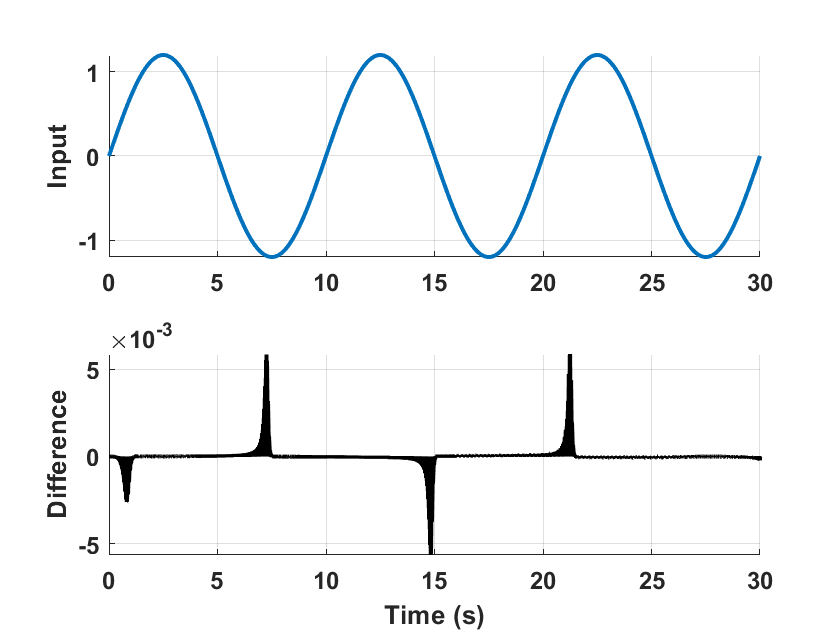

% Euler and VDP Analysis
mySS = pickDynamicSystem('vdp');
hGoodEuler = 0.000001;
hGoodRK = 0.0005;
% [eu1.t, eu1.y, eu1.u] = mySim(mySS,30,hGoodEuler,'euler');
% [eu2.t, eu2.y, eu2.u] = mySim(mySS,30,hGoodEuler/10,'euler');
% euler_001_to_01_Plot = compareData(eu1,eu2,1); % state #2

% Add some code here for the Van der Pol time step analysis needed for the
% report.

[rk1.t, rk1.y, rk1.u] = mySim(mySS,30,hGoodRK,'rk4');
[rk2.t, rk2.y, rk2.u] = mySim(mySS,30,hGoodRK/10,'rk4');
rk_hgoodrk_to_hggodrkh_Plot = compareData(rk1,rk2,1); % state #1

Fig.5 hGoodRK analysis/comparison

In VDP comparison the time step **hGoodRk** is determined such that difference between **hGoodRK** and **hGoodRK/10** is less than 0.01 and the hGoodRK I choose is $0\ldotp 0005$, as it gives me the difference of around $0\ldotp 0058$. Similarly, I found hGoodEuler = 0.000001. Now, we will see the difference betwee hGoodRK and hGoodEuler.

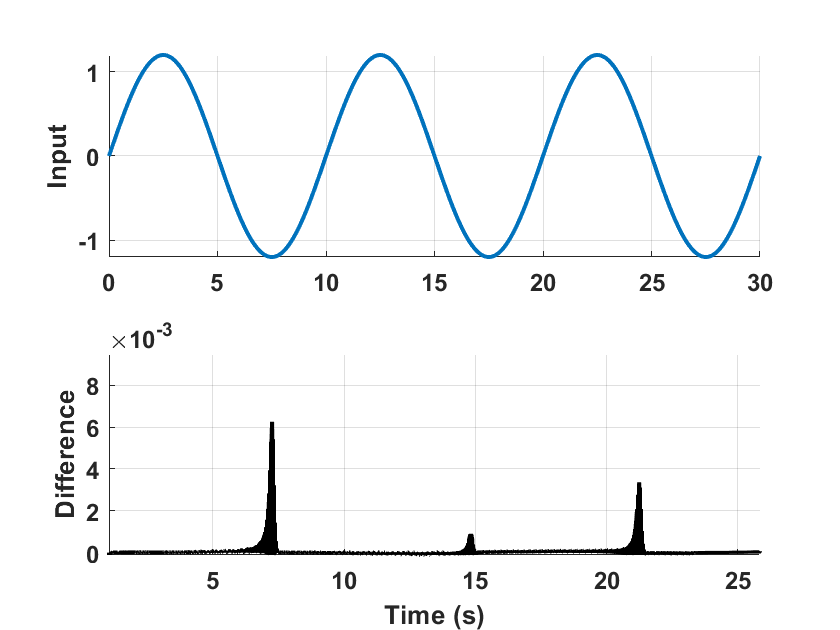


[rk1.t, rk1.y, rk1.u] = mySim(mySS,30,hGoodRK,'rk4');
[eu3.t, eu3.y, eu3.u] = mySim(mySS,30,hGoodEuler,'euler');
hgoodrk_to_hgoodeuler_plot = compareData(rk1,eu3,1); % state #1

Fig.6 hGoodRK and hGoodEuler comaprison

The difference between hGoodRK and hGoodEuler is somewhat similar to the comparison of hGoodRK and is less than 0.01. Therefore, we can use RK-4 integration method instead of euler for DS-3 (Vanderpol) as it has upper hand when it comes to the error accuracy or small error Vs step time.

### *Conclusion*

Selecting an integraton method and timestep is an important part of conducting the simulation of any dynamic system. The level of accuracy one wants, or the error magnitude one desire for in their simulation, all these factors plays a role while selecting an integration method and time step for it. The analysis executed in this project showed that, selecting higher order integration method such as RK-4 can make us select bit larger time step with minimal error magnitude, whereas, selecting lower order integration method such as Euler, can produce similar error magnitude but with quite smaller time step, wich might be stressful for your computer, or computation time can be get higher. Therefore, choosing optimal Integration method with appropriate time step is a key to the successful simulation. 

warning("off")


% DONE!

%% Helper Functions


function mySS = pickDynamicSystem(sysName)
% mySS PICKDYNAMICSYSTEM(sysName) creates a cell array that describes the
% dynamic system: LTI, LTV, or van Der Pol

  switch lower(sysName)
      case 'lti'
        mySS = {@f1,@g,@u1,2.0}; % DS 1: x' = -4x + u, x0 = 2
    case 'ltv'
        mySS = {@f2,@g,@u2,[0 0]}; % DS 2: LTV, x0 = [0 0]
    case 'vdp'
        mySS = {@f3,@g,@u3,[0;0]'}; % DS 3: Van der Pol, x0 = [0 0]      
    otherwise
      error('oops');
  end
end

function h = verifyLTI
% h = VERIFyLTI Uses the LTI system to verify that your integration
% schemes are working and to compare the results of using Euler, AB-2
% and RK-4. It returns a handle to the resulting plot.

  ic    = 2.0; % initial condition
  tEnd  = 2.0; % end time, s
  tStep = 0.01; % time step, s

  % DS 1: x' = -4x + u, x0 = 2
  mySS = {@f1,@g,@u0,2.0};   

  % Since all the time steps are the same, we'll just calculate one of
  % them, same for the inputs.
  [t, eu.y, ~] = mySim(mySS,tEnd,tStep,'euler');
  [~, ab.y, ~] = mySim(mySS,tEnd,tStep,'ab2'  );
  [~, rk.y, ~] = mySim(mySS,tEnd,tStep,'rk4'  );

  % Exact solution
  yExact = ic*exp(-4*t);

  % Plot settings
  FS = 12; % font size
  LW =  1.5; % line width
  
  % In case you have some open figures... these lines will find an
  % available id for the new figure
  figs = findobj('type','figure'); % find all the open figures
  id   = length(figs) + 1;          % create an id for this fig

  % Create a new figure window and axes
  h.fig  = figure(id);

  % Plot the data using zero order hold between points, stairs.
  [euT,euY] = stairs(t,eu.y-yExact);   % create stair data for the outputs
  [abT,abY] = stairs(t,ab.y-yExact);   % create stair data for the outputs
  [rkT,rkY] = stairs(t,rk.y-yExact);   % create stair data for the outputs
  
  % Use a subplot for the exact response and more for each of the error
  % plots. The range is too large to show on one plot.
  h.ax(1) = subplot(4,1,1);hold on; 
  h.ln(1) = line(t,yExact);grid;
  y.ylb(1) = ylabel('Exact');
  y.ttl(1) = title('Verification plot');

  h.ax(2) = subplot(4,1,2);
  h.ln(2) = line(euT,euY);grid;
  y.ylb(2) = ylabel('Euler Error');

  h.ax(3) = subplot(4,1,3);  
  h.ln(3) = line(abT,abY);grid;
  y.ylb(3) = ylabel('AB-2 Error');

  h.ax(4) = subplot(4,1,4);  
  h.ln(4) = line(rkT,rkY);grid;
  y.ylb(4) = ylabel('RK-4 Error');  

  % Format the figure
  for i=1:length(h.ln)
    h.ax(i).FontWeight = 'Bold';
    h.ax(i).FontSize = FS;
    h.ln(i).LineWidth = LW;
  end  

  % Enlarge the figure
  h.fig.Position = [440   233   821   564];

end

function h = plotData(simData,sysName)
% h = PLOTDATA(simData,sysName) creates plots customized to the dynamic
% system given in sysName

  % General Settings

  % plot settings
  FS = 12; % font size
  LW =  1.5; % line width

  % In case you have some open figures... these lines will find an
  % available id for the new figure
  figs =  findobj('type','figure'); % find all the open figures
  id   = length(figs) + 1;          % create an id for this fig

  % Create a new figure window and axes
  h.fig   = figure(id);
  h.axs   = axes; 

  % Customized Plots

  switch lower(sysName)
      case 'lti'
        % Plot the data using zero order hold between points, stairs.
        [x,y]   = stairs(simData.t,simData.y);   % create stair data for the output
        h.ln(1) = line(x,y,'Color','k'); % output
        [x,y]   = stairs(simData.t,simData.u);   % create stair data for the input
        h.ln(2) = line(x,y,'Color','b'); % input

        % Formatting
        grid;  
        h.xlb   = xlabel('Time (s)','FontSize',FS);
        h.ylb   = ylabel('Input and Output','FontSize',FS);
        h.ttl   = title(sysName,"(h = 0.01s)");
        h.leg   = legend('y','u');

     case {'ltv','vdp'}

        % Plot the data using zero order hold between points, stairs.
        h.axs(1)= subplot(2,1,1);  
        [x,y]   = stairs(simData.t,simData.u);   % create stair data for the input
        h.ln(1) = line(x(:,1),y(:,1),'Color','b'); % input 
        grid;
        h.xlb(1)   = xlabel('Time (s)','FontSize',FS);
        h.ylb(1)   = ylabel('u','FontSize',FS);
        h.ttl   = title(sysName,"(h = 0.01s)");
  
        h.axs(2)= subplot(2,1,2);
        [x,y]   = stairs(simData.t,simData.y);   % create stair data for the output
        h.ln(2) = line(x(:,1),y(:,1),'Color','k'); % x1
        h.ln(3) = line(x(:,2),y(:,2),'Color','r'); % 
        grid;
        h.leg   = legend('x_1','x_2');
        h.xlb(2)   = xlabel('Time (s)','FontSize',FS);
        h.ylb(2)   = ylabel('States','FontSize',FS);      
    otherwise
      error('oops');
  end  

  % More General Settings
  for i=1:length(h.axs)
    h.axs(i).FontWeight  = 'Bold';
    h.axs(i).FontSize    = FS;
  end

  for i=1:length(h.ln)
    h.ln(i).LineWidth = LW;
  end  

end

function h = compareData(d1,d2,sN)
% h = COMPAREDATA(d1,d2,sN) compares the sN output of the two data
% sets using an error plots. It assumes that both data sets have the same
% end time, but, different time steps.

  % plot settings
  FS = 12; % font size
  LW =  2; % line width

  % In case you have some open figures... these lines will find an
  % available id for the new figure
  figs =  findobj('type','figure'); % find all the open figures
  id   = length(figs) + 1;          % create an id for this fig

  % Create a new figure window and axes
  h.fig   = figure(id);

  % Input data
  h.ax(1) = subplot(2,1,1);
  h.ln(1) = line(d1.t,d1.u(:,1));grid
  h.ylb(1) = ylabel('Input','FontSize',FS);

  % The time points for the data may have different steps, so, we must make
  % one long data set for each.
  if length(d1.t) > length(d2.t)
      %d1.y = d1.y(:,sN);
      tmpY = interp1(d2.t,d2.y,d1.t,'previous');
      d2.t = d1.t;
      d2.y = tmpY;
  else
      %d1.y = d1.y(:,sN);
      tmpY = interp1(d1.t,d1.y,d2.t,'previous');
      d1.t = d2.t;
      d1.y = tmpY;      
  end

  h.ax(2) = subplot(2,1,2);
  % Plot the data using zero order hold between points, stairs.
  [x,y]   = stairs(d1.t,d1.y(:,sN)-d2.y(:,sN));   % create stair data for the output
  h.ln(2) = line(x,y,'Color','k'); % output

  % Formatting
  grid;  
  h.xlb   = xlabel('Time (s)','FontSize',FS);
  h.ylb   = ylabel('Difference','FontSize',FS);

  for i=1:length(h.ln)
    h.ln(i).LineWidth = LW;
    h.ax(i).FontWeight = 'Bold';
    h.ax(i).FontSize = FS;    
  end  
end
